# Supplement B3: Simulation of NMR spectra at zero and ultra-low field - Case of XA spin system

Supplementary material to "Simulation of NMR spectra at zero- and ultra-low field from A to Z – a tribute to Prof. Konstantin L’vovich Ivanov" [https://doi.org/10.5194/mr-2022-18](https://doi.org/10.5194/mr-2022-18) 

*Q. Stern and K. Sheberstov*

This script shows how to simulate ZULF spectra for an XA spin system. It was used to generate Figures 4 and 5 of the paper.

Figure path and plot options

clear all
FigurePath='C:\Users\quent\Documents\Projects\Tutorial paper on ZULF\Figures\';
FigureWidth=11;             % Figure width in cm
FigureHeight=3;             % Figure height in cm
FigureWidth2=12;            % Nutation figure width in cm
FigureHeight2=3;            % Nutation figure height in cm
c1=[0    0.4470    0.7410]; % Figure color 1 
c2=[1 1 1]*0.5;             % Figure color 2
lw=1;                       % Figure linewidth
YlimSpectra=[0 0.4];        % Figure spectra y-limits in pT
YlimFID=[-60 60];           % Figure FID y-limits in pT
Xlim=[0 160];               % Figure spectra x-limits

## General paramaters and operators

#### Spin system paramaters

JIS=140;            % J-coupling between I and S in Hz
gI= 67.262e6;       % Gyromagnetic ration of spin I (13C) in rad.s-1.T-1
gS=276.513e6;       % Gyromagnetic ration of spin S (1H) in rad.s-1.T-1

#### Experimental conditions

Bpol=2;             % Field for prepolarization in T
T=298;              % Temperature of prepolarization in K
Bx=0.5e-6;          % Magnetic field along x for ultra-low field experiments in T
Bpulse=50e-6;       % Magnetic field along x during DC pulses in T
NA=6.02e23;         % Avogadro's number in mol-1
C=27;               % Molecule concentration in mol.L-1
V=100e-6;           % Sample volume in L
r=0.01;             % Distance between the center of the sample and the center of the detector in m

#### Physical constants

hbar=1.05457e-34;   % Reduced Planck constant in J.s/rad
kB=1.3806485e-23;   % Boltzmann constant J.K-1
mu0=4*pi*1e-7;      % Permeability of free space dived in T.m.A-1 

#### Parameters for propagation

taq=5;              % Propagation/acquisition time in s
K=2^12;             % Number of points in the FID
L=2^16;             % Number of points in the FID with zero filling
T2=1;               % Coherence time constant in s
dt=taq/K;           % Time interval for propagation in s
t=(0:K-1)'/K*taq;   % Time axis in s

#### Frequency axis

f=(K-1)/taq;        % Sampling frequency in Hz
nu=(0:L/2-1)/L*f;   % Frequency axis in Hz (only positive frequencies)

#### Integration range

numin=138;          % Lower boundary for signal integration in Hz
numax=142;          % Higher boundary for signal integration in Hz

#### Definition of operators

Pauli matrices

e =[1 0;  0 1];
sx=[0 1;  1 0];
sy=[0 -1i;1i 0];
sz=[1 0;  0 -1];

Operators for spin I

Ix=kron(sx/2,e); 
Iy=kron(sy/2,e);
Iz=kron(sz/2,e);

Operators for spin S

Sx=kron(e,sx/2); 
Sy=kron(e,sy/2);
Sz=kron(e,sz/2);

Unity operator

E=kron(e,e);

#### Initial density matrix

Polarization of spin I at equilibrium in the prepolarizing magnet calculated using Boltzman distribution

PI=tanh(hbar*Bpol*gI/kB/T/2);

Polarization of spin S at equilibrium in the prepolarizing magnet calculated using Boltzman distribution

PS=tanh(hbar*Bpol*gS/kB/T/2);

Initial density matrix of spin I and S at equilibrium in the prepolarizing magnet 

Iz_2by2=sz/2;
rhoI=e/2+PI*Iz_2by2;
rhoS=e/2+PS*Iz_2by2;
rho_eq=kron(rhoI,rhoS);

Modification of the density matrix removing the identity

NumberOfSpins=2;
rho_eq=rho_eq-eye(2^NumberOfSpins)/2^NumberOfSpins;

#### Hamiltonian and propagators

Zeeman Hamiltonian as a function of field along x, y and z

HZ=@(Bx, By, Bz) -gI*(Bx*Ix+By*Iy+Bz*Iz) -gS*(Bx*Sx+By*Sy+Bz*Sz);

J Hamiltonian

HJ=2*pi*JIS*(Ix*Sx+Iy*Sy+Iz*Sz);

Total Hamiltonian

H=@(Bx, By, Bz) HJ+HZ(Bx, By, Bz);

Propagators at zero and ultra-low field

U_ZF =expm(-1i*dt*H(0,0,0));
U_ULF=expm(-1i*dt*H(Bx,0,0));

Observable operator: total field along z in pT at distance r from the sample (in the point dipole approximation)

N=NA*C*V;
O=(gI*Iz+gS*Sz)*N*hbar*1e12*mu0/2/pi/r^3;

## Sudden drop experiments

#### Zero field case

% Vector for the time domain signal
TDS_sudden_ZF=zeros(K,1);

% Initialization of the density matrix
rho=rho_eq;           
for k=1:K
    % Computes the expectation value of the field along z
    TDS_sudden_ZF(k)=real(trace(O*rho));
    
    % Propagates during dt
    rho=U_ZF*rho*U_ZF';
end

% Apodization - line broadening
TDS_sudden_ZF=TDS_sudden_ZF.*exp(-t/T2);

% Fourier transform
FDS_sudden_ZF = FourierTransform(TDS_sudden_ZF,L);

% Intensity of the sudden drop signal
I_sudden_drop=sum(FDS_sudden_ZF(nu>numin & nu<numax))

I_sudden_drop = 9.1326

#### Ultra-low field case

% Vector for the time domain signal
TDS_sudden_ULF=zeros(K,1);

% Initialization of the density matrix
rho=rho_eq;          
for k=1:K
    % Computes the expectation value of the field along z
    TDS_sudden_ULF(k)=real(trace(O*rho));
    
    % Propagates during dt
    rho=U_ULF*rho*U_ULF';
end

% Relaxation
TDS_sudden_ULF=TDS_sudden_ULF.*exp(-t/T2);

% Fourier transform
FDS_sudden_ULF = FourierTransform(TDS_sudden_ULF,L);

####  Plot the results

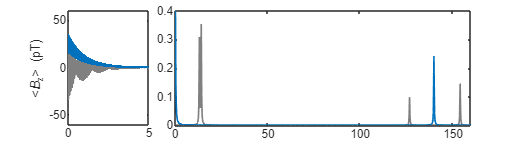

figure("Units","centimeters","Position",[0 0 FigureWidth FigureHeight])
subplot(1,4,1)
plot(t,TDS_sudden_ULF,'LineWidth',lw,'color',c2), hold on
plot(t,TDS_sudden_ZF,'LineWidth',lw,'color',c1), hold off
xlim([0 taq]), %xlabel('Time (s)')
ylabel('<{\itB}_z> (pT)')
ylim(YlimFID)
set(gca,'fontsize',7)

subplot(1,4,[2 4])
plot(nu,FDS_sudden_ULF,'LineWidth',lw,'color',c2), hold on
plot(nu,FDS_sudden_ZF,'LineWidth',lw,'color',c1), hold off
xlim(Xlim), %xlabel('Frequency (Hz)')
set(gca,'fontsize',7)
ylim(YlimSpectra)

exportgraphics(gcf,fullfile(FigurePath, 'XA_system_sudden_drop.pdf'),'ContentType','vector')

## Adiabatic field drop

#### Propagation of the adiabatic field drop

B_start=200e-6; % Magnetic field at the start of the decay in T
t_adia=0.5;     % Time of the adiabatic field drop in s
T_adia=0.05;    % Decay time constant of the adiabatic field drop in s
M=5000;         % Number of discrete points for the adiabatic field drop

Time intervals for adiabatic field drop

dt_adia=t_adia/M;

Field profile of the adiabatic field drop: exponential decay generated by a Helmholtz coil.

B_adia=B_start*(exp(-(0:M-1)/M*t_adia/T_adia)-exp(-t_adia/T_adia))/(1-exp(-t_adia/T_adia));

Propagation

rho_adia=rho_eq;
for k=1:M
    U=expm(-1i*dt_adia*H(0,0,B_adia(k)));
    rho_adia=U*rho_adia*U';
end

#### Zero field case

% Vector for the time domain signal
TDS_AFD_ZF=zeros(K,1);

% Initialization of the density mat
rho=rho_adia;      
for k=1:K
    % Computes the expectation value of the field along z
    TDS_AFD_ZF(k)=real(trace(O*rho));
    
    % Propagates during dt
    rho=U_ZF*rho*U_ZF';
end

% Apodization - line broadening
TDS_AFD_ZF=TDS_AFD_ZF.*exp(-t/T2);

% Fourier transform
FDS_AFD_ZF = FourierTransform(TDS_AFD_ZF,L);

#### Ultra-low field case

Propagation

% Vector for the time domain signal
TDS_AFD_ULF=zeros(K,1);

% Initialization of the density mat
rho=rho_adia;      
for k=1:K
    % Computes the expectation value of the field along z
    TDS_AFD_ULF(k)=real(trace(O*rho));
    
    % Propagates during dt
    rho=U_ULF*rho*U_ULF';
end

% Relaxation
TDS_AFD_ULF=TDS_AFD_ULF.*exp(-t/T2);

% Fourier transform
FDS_AFD_ULF = FourierTransform(TDS_AFD_ULF,L);

####  Plot the results

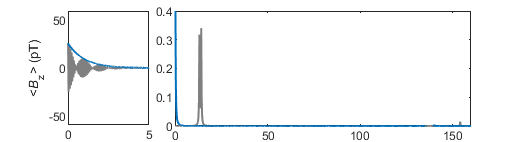

figure("Units","centimeters","Position",[0 0 FigureWidth FigureHeight])
subplot(1,4,1)
plot(t,TDS_AFD_ULF,'LineWidth',lw,'color',c2), hold on
plot(t,TDS_AFD_ZF,'LineWidth',lw,'color',c1), hold off
xlim([0 taq]), %xlabel('Time (s)')
ylim(YlimFID), ylabel('<{\itB}_z> (pT)')
set(gca,'fontsize',7)

subplot(1,4,[2 4])
plot(nu,FDS_AFD_ULF,'LineWidth',lw,'color',c2), hold on
plot(nu,FDS_AFD_ZF,'LineWidth',lw,'color',c1), hold off
xlim(Xlim), %xlabel('Frequency (Hz)')
set(gca,'fontsize',7)
ylim(YlimSpectra)

exportgraphics(gcf,fullfile(FigurePath, 'XA_system_adiabatic.pdf'),'ContentType','vector')

### Propgation of the pulse along Z

Pulse length in s

tpulse=150e-6;

Pulse propagator and density operator after the pulse

Upulse=expm(-1i*tpulse*HZ(0,0,Bpulse));
rho_afterpuse=Upulse*rho_adia*Upulse';

#### Zero field case

% Vector for the time domain signal
TDS_Z_pulse_ZF=zeros(K,1);

% Initialization of the density mat
rho=rho_afterpuse;  
for k=1:K
    % Computes the expectation value of the field along z
    TDS_Z_pulse_ZF(k)=real(trace(O*rho));
    
    % Propagates during dt
    rho=U_ZF*rho*U_ZF';
end

% Apodization - line broadening
TDS_Z_pulse_ZF=TDS_Z_pulse_ZF.*exp(-t/T2);

% Fourier transform
phase=pi/2;
FDS_Z_pulse_ZF = FourierTransform(TDS_Z_pulse_ZF*exp(1i*phase),L);

#### Ultra-low field case

% Vector for the time domain signal
TDS_Z_pulse_ULF=zeros(K,1);

% Initialization of the density mat
rho=rho_afterpuse;  
for k=1:K
    % Computes the expectation value of the field along z
    TDS_Z_pulse_ULF(k)=real(trace(O*rho));
    
    % Propagates during dt
    rho=U_ULF*rho*U_ULF';
end

% Relaxation
TDS_Z_pulse_ULF=TDS_Z_pulse_ULF.*exp(-t/T2);

% Fourier transform
phase=pi/2;
FDS_Z_pulse_ULF = FourierTransform(TDS_Z_pulse_ULF*exp(1i*phase),L);

####  Plot the results

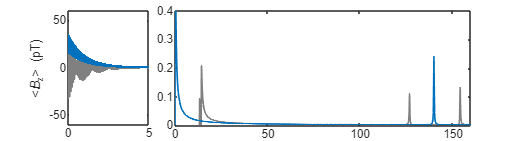

figure("Units","centimeters","Position",[0 0 FigureWidth FigureHeight])
subplot(1,4,1)
plot(t,TDS_Z_pulse_ULF,'LineWidth',lw,'Color',c2), hold on
plot(t,TDS_Z_pulse_ZF,'LineWidth',lw,'Color',c1), hold off
xlim([0 taq]), %xlabel('Time (s)')
ylim(YlimFID), ylabel('<{\itB}_z> (pT)')
set(gca,'fontsize',7)

subplot(1,4,[2 4])
plot(nu,FDS_Z_pulse_ULF,'LineWidth',lw,'Color',c2), hold on
plot(nu,FDS_Z_pulse_ZF,'LineWidth',lw,'Color',c1), hold off
xlim(Xlim), %xlabel('Frequency (Hz)')
set(gca,'fontsize',7)
ylim(YlimSpectra)

exportgraphics(gcf,fullfile(FigurePath, 'XA_system_adiabatic_and_pulse_Z.pdf'),'ContentType','vector')

## Pulse along X

Pulse length in s

tpulse=910e-6;

Pulse propagator and density operator after the pulse

Upulse=expm(-1i*tpulse*HZ(Bpulse,0,0));
rho_afterpuse=Upulse*rho_adia*Upulse';

#### Zero field case

% Vector for the time domain signal
TDS_X_pulse_ZF=zeros(K,1);

% Initialization of the density mat
rho=rho_afterpuse;  
for k=1:K
    % Computes the expectation value of the field along z
    TDS_X_pulse_ZF(k)=real(trace(O*rho));
    
    % Propagates during dt
    rho=U_ZF*rho*U_ZF';
end

% Apodization - line broadening
TDS_X_pulse_ZF=TDS_X_pulse_ZF.*exp(-t/T2);

% Fourier transform
FDS_X_pulse_ZF = FourierTransform(TDS_X_pulse_ZF,L);

#### Ultra-low field case

% Vector for the time domain signal
TDS_X_pulse_ULF=zeros(K,1);

% Initialization of the density mat
rho=rho_afterpuse;  
for k=1:K
    % Computes the expectation value of the field along z
    TDS_X_pulse_ULF(k)=real(trace(O*rho));
    
    % Propagates during dt
    rho=U_ULF*rho*U_ULF';
end

% Relaxation
TDS_X_pulse_ULF=TDS_X_pulse_ULF.*exp(-t/T2);

% Fourier transform
FDS_X_pulse_ULF = FourierTransform(TDS_X_pulse_ULF,L);

####  Plot the results

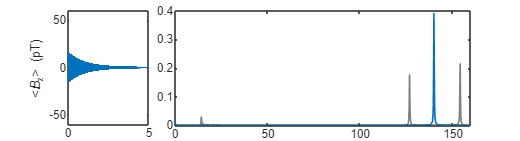

figure("Units","centimeters","Position",[0 0 FigureWidth FigureHeight])
subplot(1,4,1)
plot(t,TDS_X_pulse_ULF,'LineWidth',lw,'color',c2), hold on
plot(t,TDS_X_pulse_ZF,'LineWidth',lw,'color',c1), hold off
xlim([0 taq]), %xlabel('Time (s)')
ylim(YlimFID), ylabel('<{\itB}_z> (pT)')
set(gca,'fontsize',7)

subplot(1,4,[2 4])
plot(nu,FDS_X_pulse_ULF,'LineWidth',lw,'color',c2), hold on
plot(nu,FDS_X_pulse_ZF,'LineWidth',lw,'color',c1), hold off
xlim(Xlim), %xlabel('Frequency (Hz)')
set(gca,'fontsize',7)
ylim(YlimSpectra)

exportgraphics(gcf,fullfile(FigurePath, 'XA_system_adiabatic_and_pulse_X.pdf'),'ContentType','vector')

## Nutation curve with pulse along x

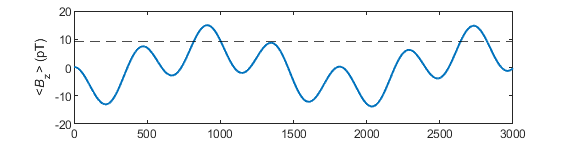

% Vector containing the pulse lengths in s
tpulse=linspace(0,3000e-6,3000);  

% Vector for signal as a function of the pulse length
I_X_pulse_nutation=zeros(length(tpulse),1);

parfor i=1:length(tpulse)
    % Vector for the time domain signal
    TDS_X_pulse_nutation=zeros(K,1);
    
    % Propagator of the pulse Hamiltonian
    Upulse=expm(-1i*tpulse(i)*HZ(Bpulse,0,0));
    
    % Initialization of the density mat
    rho=Upulse*rho_adia*Upulse';
    for k=1:K
        % Computes the expectation value of the field along z
        TDS_X_pulse_nutation(k)=real(trace(O*rho));
        
        % Propagates during dt
        rho=U_ZF*rho*U_ZF';
    end
    
    % Apodization - line broadening
    TDS_X_pulse_nutation=TDS_X_pulse_nutation.*exp(-t/T2); 
    
    % Fourier transform
    FDS_X_pulse_nutation=FourierTransform(TDS_X_pulse_nutation,L);
    
    % Chops the relevant portion of the spectrum
    S_=FDS_X_pulse_nutation(nu>numin & nu<numax);
    
    % Integrates the portion of the spectrum
    I_X_pulse_nutation(i)=sum(S_);
end
figure("Units","centimeters","Position",[0 0 FigureWidth2 FigureHeight2])
plot(tpulse*1e6,I_X_pulse_nutation,'LineWidth',lw)
yline(I_sudden_drop,'k--')
ylabel('<{\itB}_z> (pT)'), %xlabel('Pulse length (\mus)')
ylim([-20 20])
set(gca,'fontsize',7)

exportgraphics(gcf,fullfile(FigurePath, 'XA_ZULF_nutation_curve_X.pdf'),'ContentType','vector')

disp(['Signal ratio with respect to sudden drop: ' num2str(max(I_X_pulse_nutation)/I_sudden_drop)])

Signal ratio with respect to sudden drop: 1.64


## Nutation curve with pulse along z

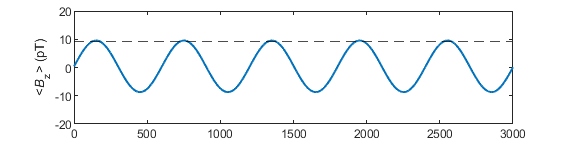

% Vector containing the pulse lengths in s
tpulse=linspace(0,3000e-6,3000);  

% Vector for signal as a function of the pulse length
I_Z_pulse_nutation=zeros(length(tpulse),1);

parfor i=1:length(tpulse)
    % Vector for the time domain signal
    TDS_Z_pulse_nutation=zeros(K,1);
    
    % Propagator of the pulse Hamiltonian
    Upulse=expm(-1i*tpulse(i)*HZ(0,0,Bpulse));
    
    % Initialization of the density mat
    rho=Upulse*rho_adia*Upulse';
    for k=1:K
        % Computes the expectation value of the field along z
        TDS_Z_pulse_nutation(k)=real(trace(O*rho));
        
        % Propagates during dt
        rho=U_ZF*rho*U_ZF';
    end
    
    % Apodization - line broadening
    TDS_Z_pulse_nutation=TDS_Z_pulse_nutation.*exp(-t/T2); 
    
    % Fourier transform
    phase=pi/2;
    FDS_Z_pulse_nutation=FourierTransform(TDS_Z_pulse_nutation*exp(1i*phase),L);
    
    % Chops the relevant portion of the spectrum
    S_=FDS_Z_pulse_nutation(nu>numin & nu<numax);
    
    % Integrates the portion of the spectrum
    I_Z_pulse_nutation(i)=sum(S_);
end

figure("Units","centimeters","Position",[0 0 FigureWidth2 FigureHeight2])
plot(tpulse*1e6,I_Z_pulse_nutation,'LineWidth',lw)
yline(I_sudden_drop,'k--')
ylabel('<{\itB}_z> (pT)')
%xlabel('Pulse length (\mus)')
ylim([-20 20])
set(gca,'fontsize',7)

exportgraphics(gcf,fullfile(FigurePath, 'XA_ZULF_nutation_curve_Z.pdf'),'ContentType','vector')

## Functions

function S=FourierTransform(I,N)
    % Converts to column vector
    I=I(:);
    
    % Window function to avoid baseline shift
    I=[I(1); 2*I(2:end)];
    
    % Fourier transform
    S = real(fft(I,N))/N;
    
    % Remove negative frequencies
    S=2*S(1:N/2);
end